%Reading the Habitability dataset
PHL_Table = readtable("Project\Dataset\PHL_Data.xlsx", 'ReadVariableNames', true);
disp(PHL_Table);

    sy_snum    sy_pnum    sy_mnum    pl_orbper    pl_rade    pl_bmasse    st_teff    st_lum    st_logg    Habitable
    _______    _______    _______    _________    _______    _________    _______    ______    _______    _________

       2          1          0         326.03       12.1       6165.6       4742      2.243     2.31          0    
       1          1          0         516.22       12.3       4684.8       4213       2.43     1.93          0    
       1          1          0         185.84       12.9       1525.5       4813      1.763     2.63          0    
       1          2          0           1765       12.6       2586.7       533

%Calculating planet radius from planet mass if it is missing
for i = 1:size(PHL_Table, 1)
    if isnan(PHL_Table{i, "pl_rade"}) && not(isnan(PHL_Table{i, "pl_bmasse"}))
        if PHL_Table{i, "pl_bmasse"} < 2.04
            c = 0.00346;
            s = 0.2790;
        elseif PHL_Table{i, "pl_bmasse"} < 132
            c = -0.0925;
            s = 0.589;
        elseif PHL_Table{i, "pl_bmasse"} < 26600
            c = 1.25;
            s = -0.044;
        else
            c = -2.85;
            s = 0.881;
        end
        PHL_Table{i, "pl_rade"} = c + (PHL_Table{i, "pl_bmasse"} * s);
%Calculating planet mass from planet radius if it is missing
    elseif not(isnan(PHL_Table{i, "pl_rade"})) && isnan(PHL_Table{i, "pl_bmasse"})
        if PHL_Table{i, "pl_rade"} < 1.23
            c = 0.00346;
            s = 0.2790;
        elseif PHL_Table{i, "pl_rade"} < 11.1
            c = -0.0925;
            s = 0.589;
        else
            c = -2.85;
            s = 0.881;
        end
        PHL_Table{i, "pl_bmasse"} = (PHL_Table{i, "pl_rade"} - c) / s;
    end
end
%Removing the rows with missing values
PHL_Table = rmmissing(PHL_Table);
disp(PHL_Table);

    sy_snum    sy_pnum    sy_mnum    pl_orbper    pl_rade    pl_bmasse    st_teff    st_lum    st_logg    Habitable
    _______    _______    _______    _________    _______    _________    _______    ______    _______    _________

       2          1          0         326.03        12.1      6165.6       4742      2.243     2.31          0    
       1          1          0         516.22        12.3      4684.8       4213       2.43     1.93          0    
       1          1          0         185.84        12.9      1525.5       4813      1.763     2.63          0    
       1          2          0           1765        12.6      2586.7       533

%Normalizing the dataset using z-score
PHL_Norm_Table = normalize(PHL_Table(:, [1 2 3 4 5 6 7 8 9]));
PHL_Norm_Table.Habitable = PHL_Table.Habitable;
%Removing the sy_mnum column as it is a constant
PHL_Norm_Clean_Table = removevars(PHL_Norm_Table,{'sy_mnum'});
disp(PHL_Norm_Clean_Table);

    sy_snum     sy_pnum     pl_orbper      pl_rade       pl_bmasse      st_teff        st_lum       st_logg      Habitable
    ________    ________    __________    __________    ___________    __________    __________    __________    _________

      2.6609    -0.68065     -0.014752        1.0522         3.2645      -0.49757        3.1964       -4.7535        0    
    -0.29764    -0.68065     -0.014718         1.083         2.4314      -0.88653        3.4514       -5.6289        0    
    -0.29764    -0.68065     -0.014776        1.1753        0.65393      -0.44537        2.5419       -4.0164        0    
    -0.29764     0.18034     -0.014499        1.1291          1.251     -0.059

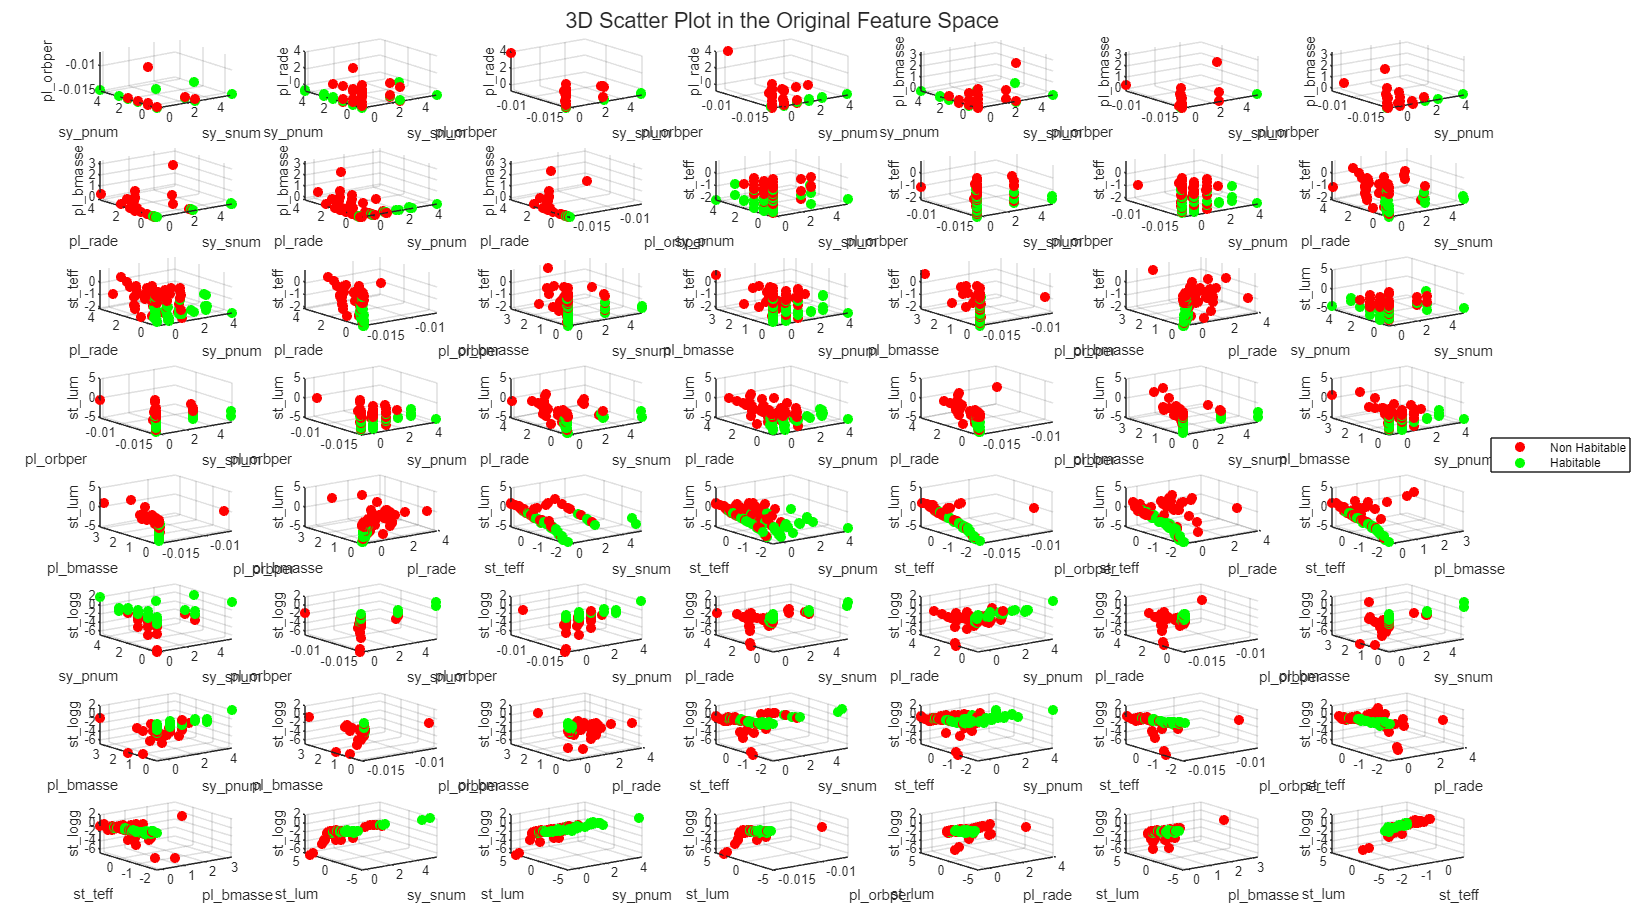

%Splitting the normalized dataset based on the habitability classes
PHL_Norm_Clean_Tables = {PHL_Norm_Clean_Table((PHL_Norm_Clean_Table{:, 9} == 0), [1 2 3 4 5 6 7 8])  PHL_Norm_Clean_Table((PHL_Norm_Clean_Table{:, 9} == 1), [1 2 3 4 5 6 7 8])};
%3D Scatter Plots before PCA
Colors = ["red", "green"];
set(0,'DefaultTextInterpreter','none');
figure('Resize', 'off', 'Units', 'normalized', 'Position', [1, 1, 60, 60]);
t = tiledlayout(8, 7, 'TileSpacing', 'compact', 'Padding', 'compact');
%Selecting random rows of the minority class size from the majority class
%so that the plots are easier to understand
randrows = randperm(size(PHL_Norm_Clean_Tables{1}, 1), size(PHL_Norm_Clean_Tables{2}, 1));
for c = 1:2
    pos = 1;
    for i = 3:8
        for j = 2:(i - 1)
            for k = 1:(j - 1)
                nexttile(pos);
                pos = pos + 1;
                if c == 1
                    scatter3(PHL_Norm_Clean_Tables{c}{randrows, k}, PHL_Norm_Clean_Tables{c}{randrows, j}, PHL_Norm_Clean_Tables{c}{randrows, i}, Colors{c}, 'filled');
                else
                    scatter3(PHL_Norm_Clean_Tables{c}{:, k}, PHL_Norm_Clean_Tables{c}{:, j}, PHL_Norm_Clean_Tables{c}{:, i}, Colors{c}, 'filled');
                end
                xlabel(PHL_Norm_Clean_Tables{c}.Properties.VariableNames(k));
                ylabel(PHL_Norm_Clean_Tables{c}.Properties.VariableNames(j));
                zlabel(PHL_Norm_Clean_Tables{c}.Properties.VariableNames(i));
                hold on;
            end
        end
    end
end
leg = legend("Non Habitable", "Habitable");
leg.Layout.Tile = 'east';
title(t, "3D Scatter Plot in the Original Feature Space");

%Performing SVD
format short;
[U, S, V] = svd(table2array(PHL_Norm_Clean_Table(:, [1 2 3 4 5 6 7 8])), "econ");
Ur = U * S;
disp(Ur);

  Columns 1 through 3

   -5.9211    2.1361   -0.1000
   -5.9732    0.4658    2.3369
   -4.2825   -0.0542    1.5622
   -0.5367    0.8855    0.1926
   -1.4062    3.1515   -4.0372
   -5.6663   -0.1958    2.2603
   -4.4338    1.7497   -0.6337
   -4.4519   -0.3305    1.5562
   -2.4963   -0.1067    0.6309
   -2.4750   -0.1564    0.6023
   -5.6075   -6.8025  -11.0759
    3.1388    4.3177    1.4300
   -2.4051    5.0434   -6.1695
   -5.5569    0.0033    2.1816
   -5.8245    1.1969    0.0738
   -0.7148    0.0248   -0.3470
   -0.6844   -0.0547   -0.3988
   -0.6923   -0.0199   -0.3680
   -2.4174    2.3292   -4.5264
   -0.9784    0.3031    0.2655
    0.0766    1.4572   -3.0132
    0.4289    1.0499   -2.9650
   -0.0076    1.6214   -2.9407
    0.8324    0.5973   -2.8922
    0.4853    0.9864   -2.9551
   -3.0449    0.0499    1.1660
    0.4135   -0.6728   -0.1917
    0.2711   -0.5133   -0.2177
    0.2315   -0.4689   -0.2249
   -2.7322   -0.0235    0.8841
   -2.7177   -0.0621    0.8585
   -1.8387    0.

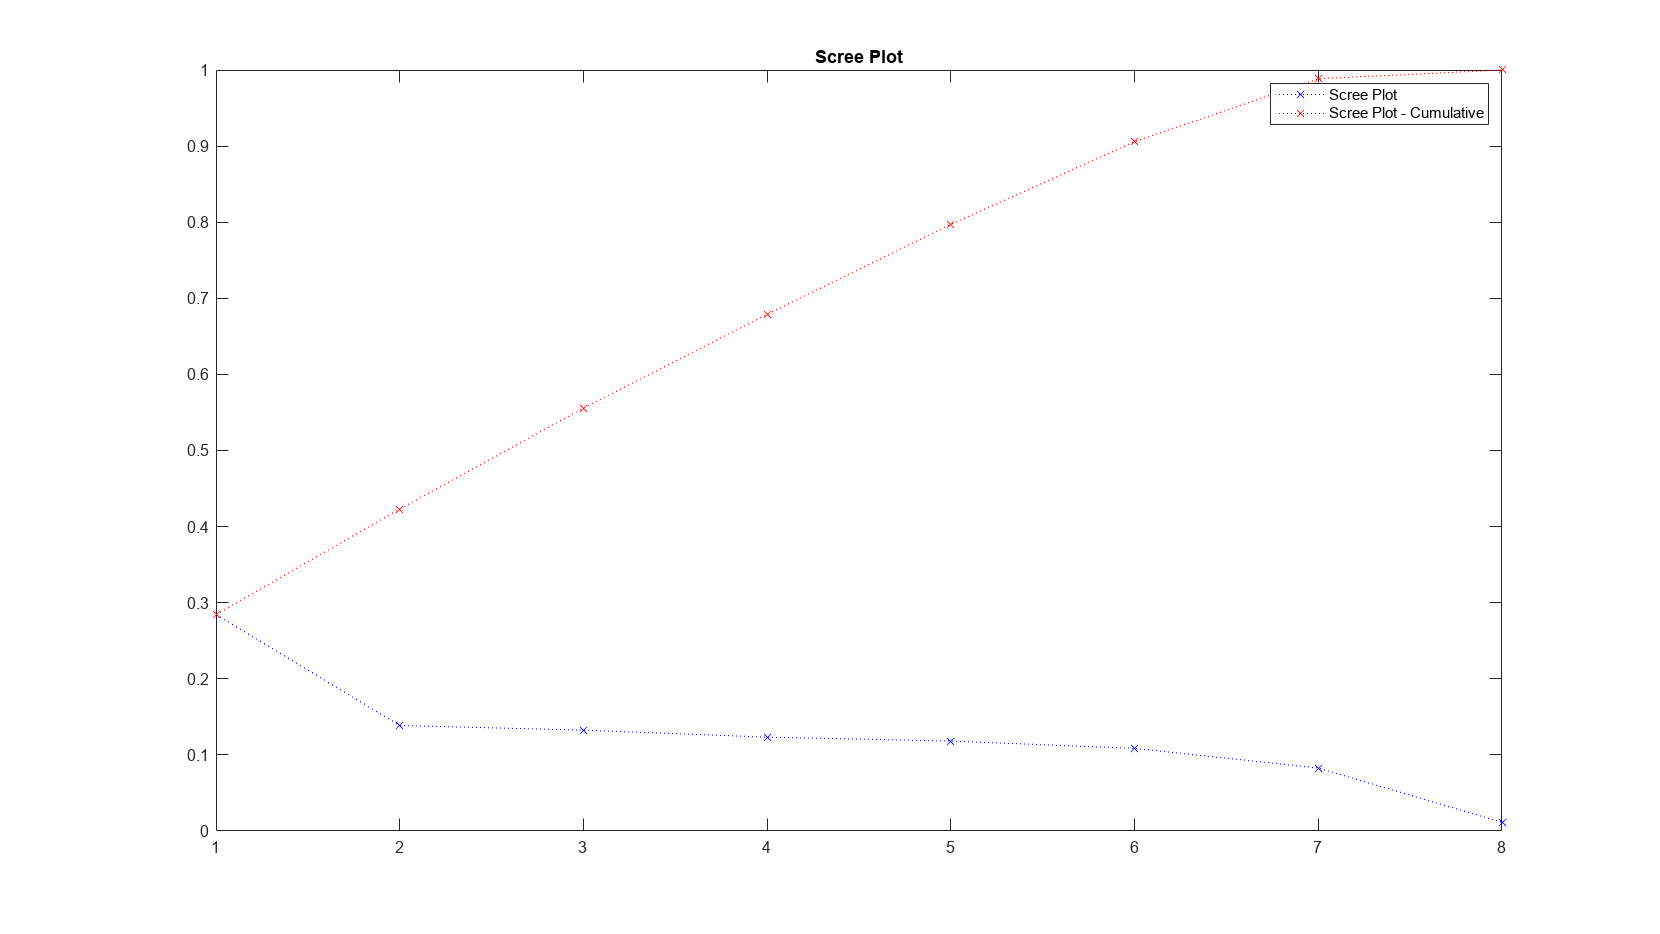

%Scree Plots
nfeatures = 8;
S2 = S^2; 
weights2 = zeros(nfeatures, 1); 
sumS2 = sum(sum(S2)); 
weightsum2 = 0; 
weight_c2 = zeros(nfeatures, 1);

for i = 1 : nfeatures 
    weights2(i) = S2(i, i) / sumS2; 
    weightsum2 = weightsum2 + weights2(i); 
    weight_c2(i) = weightsum2; 
end 

figure('Resize', 'off', 'Units', 'normalized', 'Position', [1, 1, 60, 60])
plot(weights2, 'x:b'); 
grid; 
title('Scree Plot');
hold on;
plot(weight_c2, 'x:r');
grid; 
title('Scree Plot'); 
legend("Scree Plot", "Scree Plot - Cumulative");
hold off;

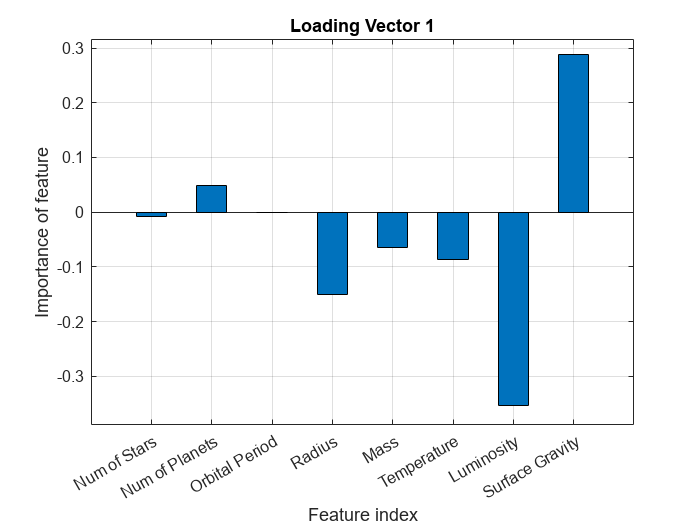

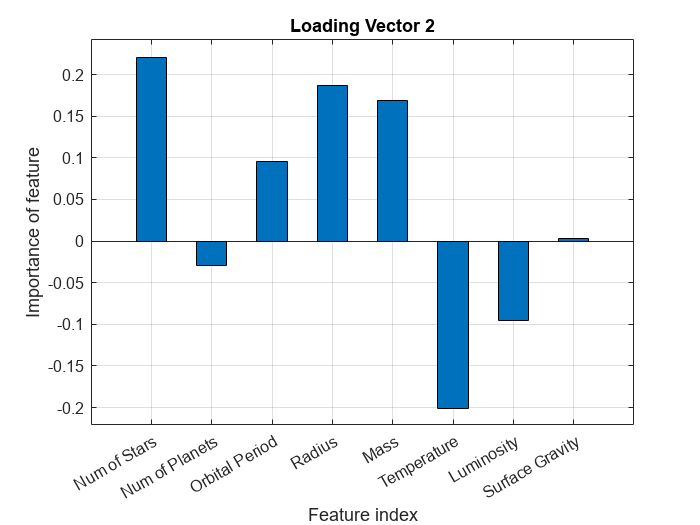

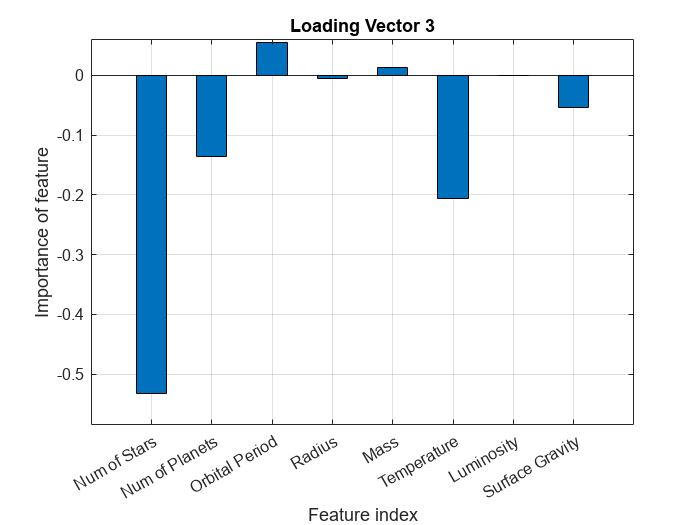

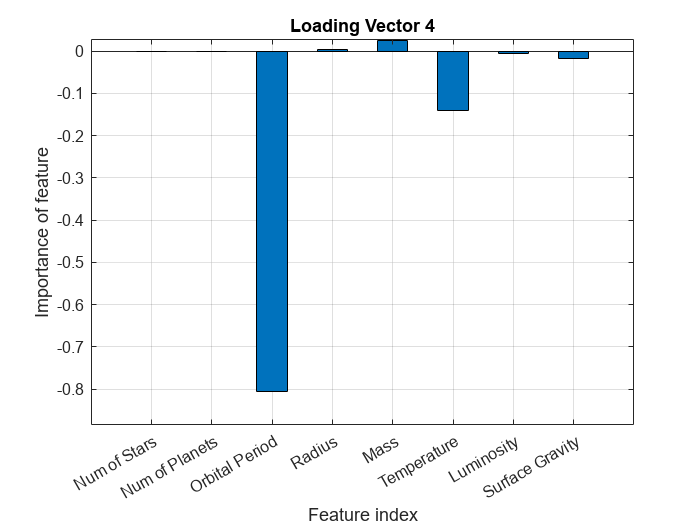

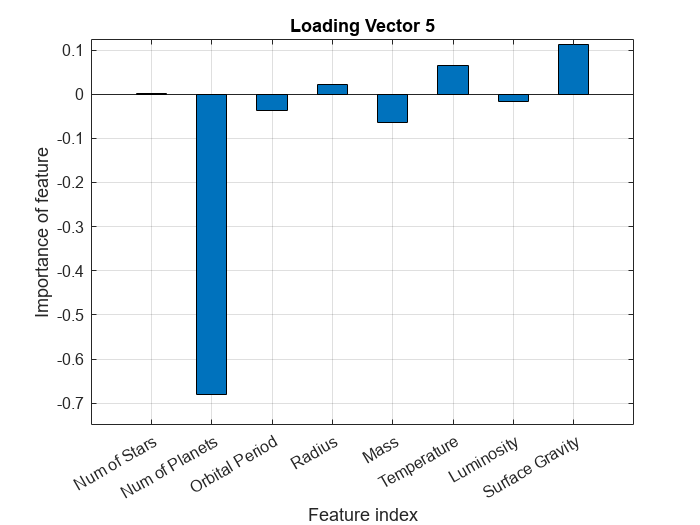

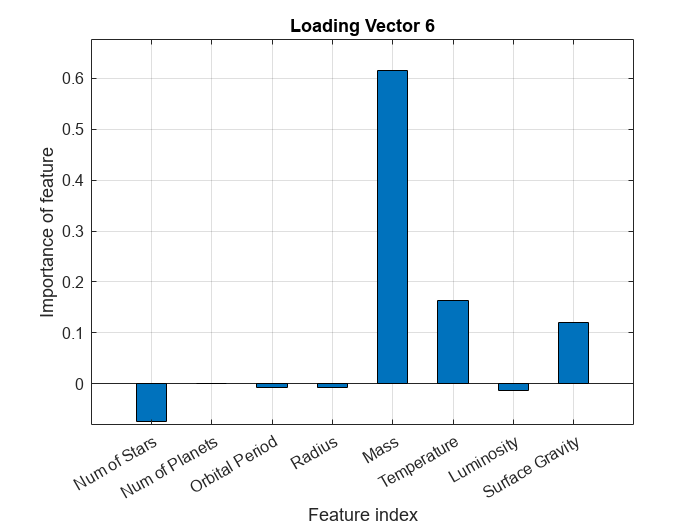

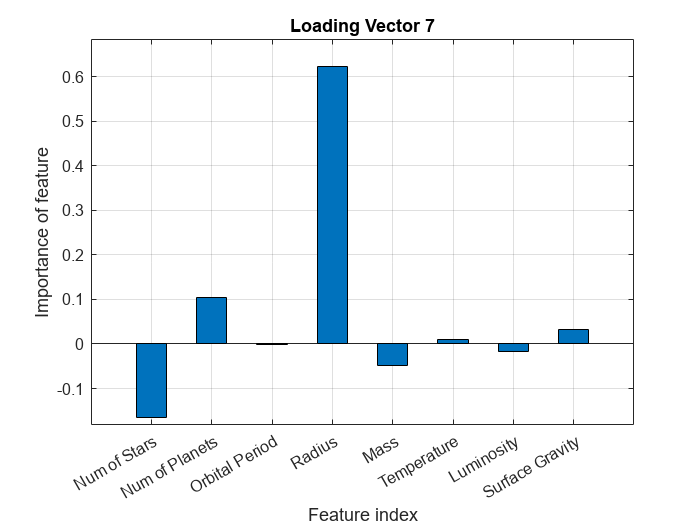

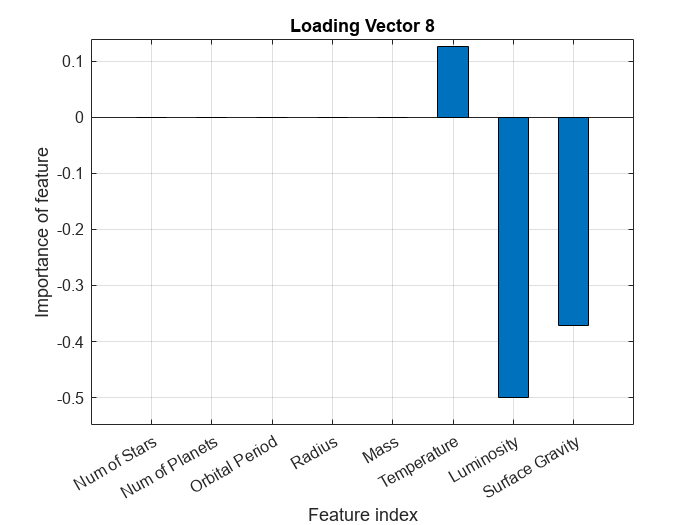

%Loading Vectors
Vsquare = zeros(1, 8); 
for i = 1:8
    for j = 1:8 
        Vsquare(i, j) = V(i, j) ^ 2; 
        if V(i, j) < 0 
            Vsquare(i, j) = Vsquare(i, j) * -1; 
        else  
            Vsquare(i, j) = Vsquare(i, j) * 1; 
        end 
    end 
end
for i = 1:8
    figure; 
    bar(Vsquare(:, i), 0.5); 
    grid;
    ymin = min(Vsquare(:, i)) + (min(Vsquare(:, i)) / 10); 
    ymax = max(Vsquare(:, i)) + (max(Vsquare(:, i)) / 10); 
    axis([0 nfeatures + 1 ymin ymax]); 
    xlabel('Feature index'); 
    ylabel('Importance of feature'); 
    [chart_title, ERRMSG] = sprintf('Loading Vector %d', i); 
    title(chart_title); 
    xticklabels(["Num of Stars", "Num of Planets", "Orbital Period", "Radius", "Mass", "Temperature", "Luminosity", "Surface Gravity"]);
end

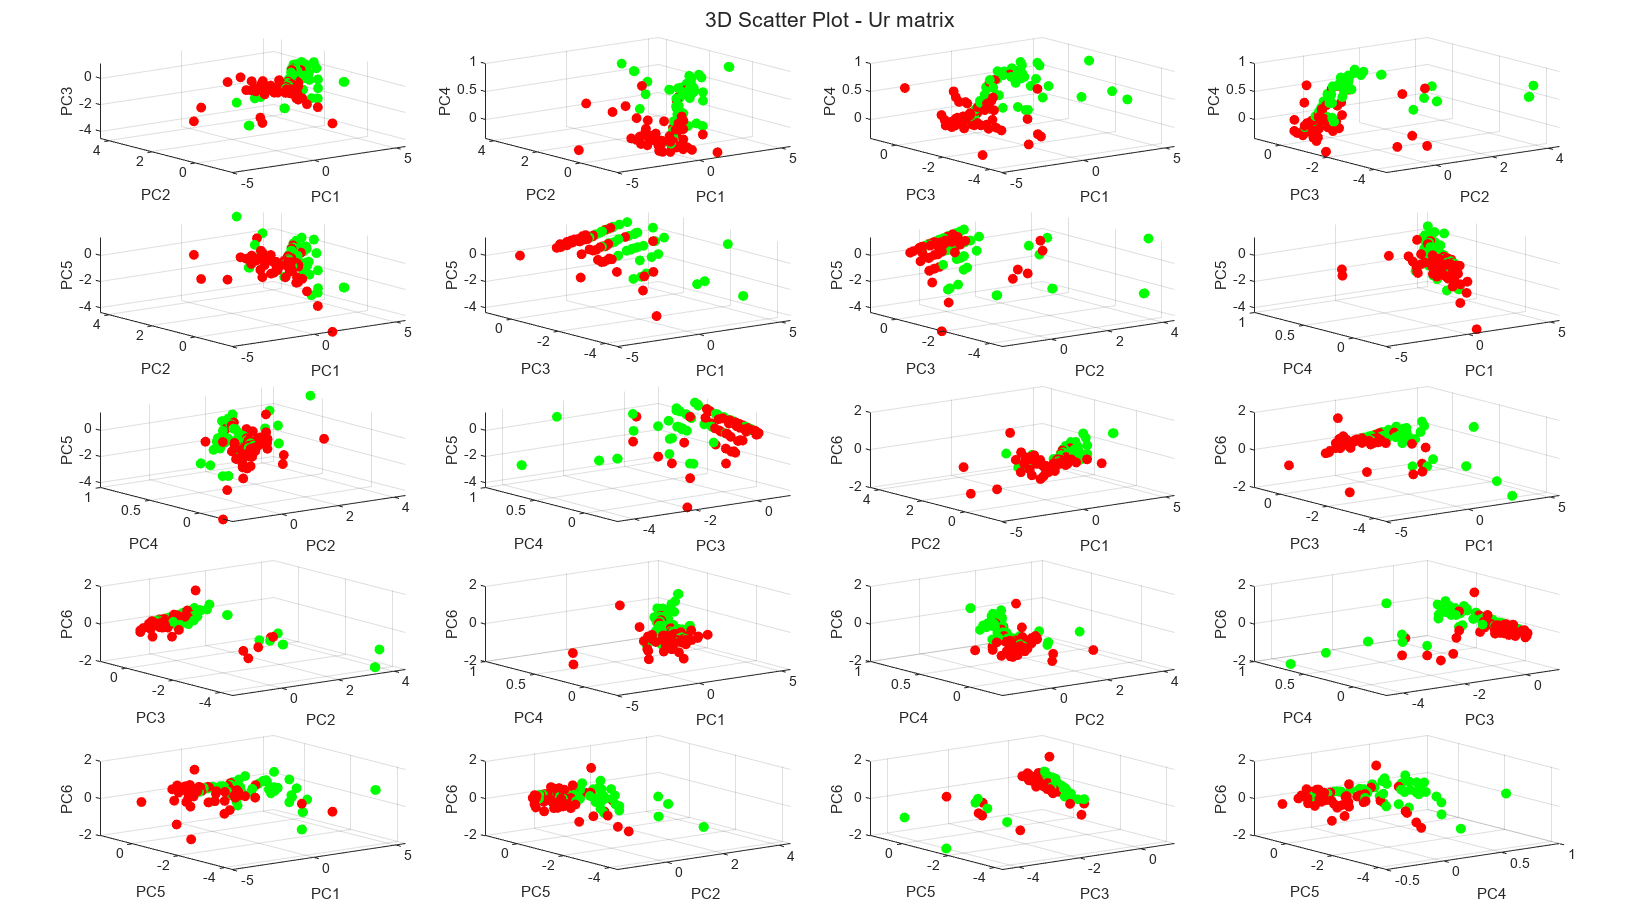

%3D Scatter Plot of Ur matrix
Ur_Matrices = {Ur((PHL_Norm_Clean_Table{:, 9} == 0), :) Ur(PHL_Norm_Clean_Table{:, 9} == 1, :)};
Colors = ["red", "green"];
set(0,'DefaultTextInterpreter','none')
figure('Resize', 'off', 'Units', 'normalized', 'Position', [1, 1, 60, 60]);
t = tiledlayout(5, 4, 'TileSpacing', 'compact', 'Padding', 'compact');
%Selecting random rows of the minority class size from the majority class
%so that the plots are easier to understand
randrows = randperm(size(PHL_Norm_Clean_Tables{1}, 1), size(PHL_Norm_Clean_Tables{2}, 1));
for c = 1:2
    pos = 1;
    for i = 3:6
        for j = 2:(i - 1)
            for k = 1:(j - 1)
                nexttile(pos);
                pos = pos + 1;
                if c == 1
                    scatter3(Ur_Matrices{c}(randrows, k), Ur_Matrices{c}(randrows, j), Ur_Matrices{c}(randrows, i), Colors{c}, 'filled');
                else
                    scatter3(Ur_Matrices{c}(:, k), Ur_Matrices{c}(:, j), Ur_Matrices{c}(:, i), Colors{c}, 'filled');
                end
                xlabel("PC" + k);
                ylabel("PC" + j);
                zlabel("PC" + i);
                hold on;
            end
        end
    end
end
%leg = legend("Non Habitable", "Habitable");
%leg.Layout.Tile = 'east';
title(t, "3D Scatter Plot - Ur matrix");

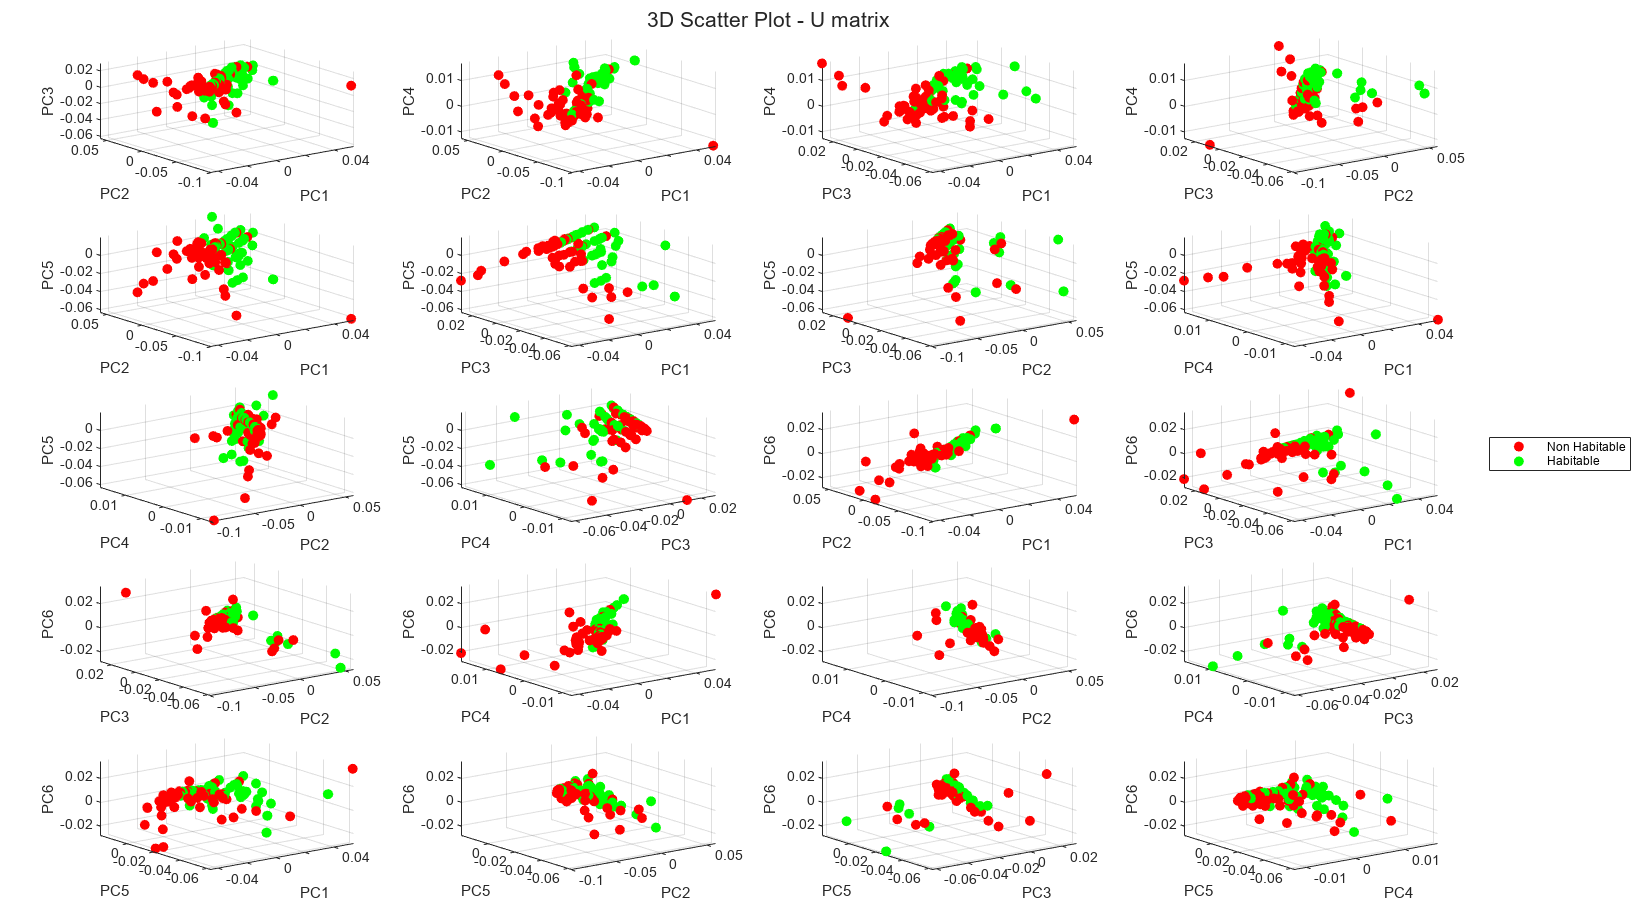

%3D Scatter Plot of U matrix
U_Matrices = {U((PHL_Norm_Clean_Table{:, 9} == 0), :) U(PHL_Norm_Clean_Table{:, 9} == 1, :)};
Colors = ["red", "green"];
set(0,'DefaultTextInterpreter','none')
figure('Resize', 'off', 'Units', 'normalized', 'Position', [1, 1, 60, 60]);
t = tiledlayout(5, 4, 'TileSpacing', 'compact', 'Padding', 'compact');
%Selecting random rows of the minority class size from the majority class
%so that the plots are easier to understand
randrows = randperm(size(PHL_Norm_Clean_Tables{1}, 1), size(PHL_Norm_Clean_Tables{2}, 1));
for c = 1:2
    pos = 1;
    for i = 3:6
        for j = 2:(i - 1)
            for k = 1:(j - 1)
                nexttile(pos);
                pos = pos + 1;
                if c == 1
                    scatter3(U_Matrices{c}(randrows, k), U_Matrices{c}(randrows, j), U_Matrices{c}(randrows, i), Colors{c}, 'filled');
                else
                    scatter3(U_Matrices{c}(:, k), U_Matrices{c}(:, j), U_Matrices{c}(:, i), Colors{c}, 'filled');
                end
                xlabel("PC" + k);
                ylabel("PC" + j);
                zlabel("PC" + i);
                hold on;
            end
        end
    end
end
leg = legend("Non Habitable", "Habitable");
leg.Layout.Tile = 'east';
title(t, "3D Scatter Plot - U matrix");

%exporting data for model building using Python
writetable(PHL_Norm_Clean_Table, 'PHL.xlsx');
writetable([array2table(Ur(:, [1 2 3 4 5 6 7 8]), 'VariableNames', ["PC1", "PC2", "PC3", "PC4", "PC5", "PC6", "PC7", "PC8"]), array2table(PHL_Norm_Clean_Table{:, 9}, 'VariableNames', "Habitable")], 'Ur.xlsx');
writetable([array2table(U(:, [1 2 3 4 5 6 7 8]), 'VariableNames', ["PC1", "PC2", "PC3", "PC4", "PC5", "PC6", "PC7", "PC8"]), array2table(PHL_Norm_Clean_Table{:, 9}, 'VariableNames', "Habitable")], 'U.xlsx');